PSD with HT

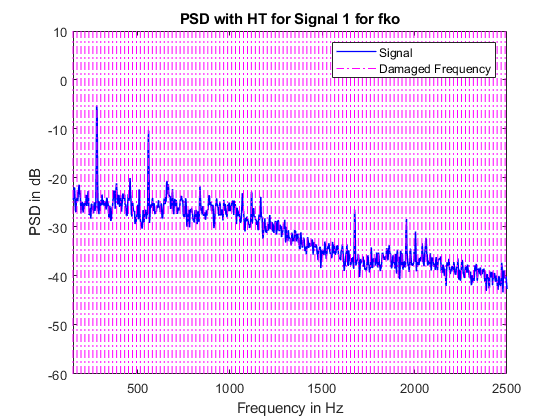

nwk = 13;
Dw = 3.7; % Rolling Element Dia in mm
Dt = 26.15; % Part Cirlce Dia in mm
alpha = 0; % Contact Angle in degrees

fko = 0.5 * fre * (1-(Dw/Dt)*cos(alpha));

fki = 0.5 * fre * (1+(Dw/Dt)*cos(alpha));

fa = 0.5 * fre * nwk * (1-(Dw/Dt)*cos(alpha));

fi = 0.5 * fre * nwk * (1+(Dw/Dt)*cos(alpha));

fwa = 0.5 * fre * (Dt/Dw) * (1-((Dw/Dt)*cos(alpha))^2);

fw = 2 * fwa;

damaged_fre = [fko ; fki ; fa ; fi ; fwa ; fw];

damaged_fre_name = { 'fko' ; 'fki' ; 'fa' ; 'fi' ; 'fwa' ; 'fw' };


nfftH = 2^14;
noverlapH = nfftH/2;

% for ii = 1 : length(x)

ii = 1;
jj = 1;
%     for jj = 1 : length(damaged_fre)

figure

rawdata{ii} = rawdata{ii} - M.mean_m(ii);

hilb = hilbert(rawdata{ii},length(rawdata{ii}));

h = sqrt(real(hilb).^2+imag(hilb).^2);

[sH,fH] = pwelch(h,window(@hann,nfftH),noverlapH,nfftH,data.fs);

%         plot(fH,sH,'r','LineWidth',1.5,'Displayname',['Signal' num2str(ii)]')

plot(fH,10*log10(sH),'b','LineWidth',1,'Displayname',['Signal' num2str(ii)]')

hold on

spacing = damaged_fre(jj,ii) .* (1:1:(10 * length(fH)) / damaged_fre(jj,ii));

plot(repmat(spacing,2,1),ylim,'-.m')

hold off

xlabel('Frequency in Hz')
ylabel('PSD in dB')
title(['PSD with HT for Signal ', num2str(ii),' for ', damaged_fre_name{jj}])
xlim([150 2500])
legend('Signal','Damaged Frequency')

% xlim([0 2*10^4])
% ylim([-40 -0])
%       end
%  end

PSD without HT

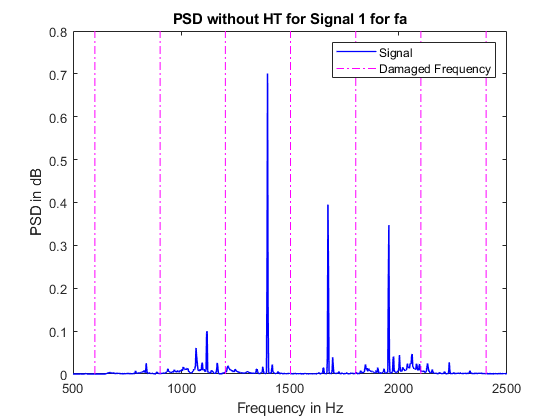

nwk = 13;
Dw = 3.7; % Rolling Element Dia in mm
Dt = 26.15; % Part Cirlce Dia in mm
alpha = 0; % Contact Angle in degrees

fko = 0.5 .* fre .* (1-(Dw/Dt).*cos(alpha));

fki = 0.5 .* fre .* (1+(Dw/Dt).*cos(alpha));

fa = 0.5 .* fre .* nwk * (1-(Dw/Dt).*cos(alpha));

fi = 0.5 .* fre .* nwk .* (1+(Dw/Dt).*cos(alpha));

fwa = 0.5 .* fre * (Dt/Dw) .* (1-((Dw/Dt)*cos(alpha))^2);

fw = 2 .* fwa;

damaged_fre = [fko ; fki ; fa ; fi ; fwa ; fw];

damaged_fre_name = { 'fko' ; 'fki' ; 'fa' ; 'fi' ; 'fwa' ; 'fw' };



nfftH = 2^14;
noverlapH = nfftH/2;

% ii = 1;
% jj = 2;

% for ii = 1 : length(x)

% for jj = 1 : length(damaged_fre)

figure

rawdata{ii} = rawdata{ii} - M.mean_m(ii);

[s,f] = pwelch(rawdata{ii},window(@hann,nfftH),noverlapH,nfftH,data.fs);

%     plot(f,10*log10(s),'r','LineWidth',1.5,'Displayname',['Signal' num2str(ii)]')

plot(f,s,'b','LineWidth',1,'Displayname',['Signal' num2str(ii)]')

hold on

spacing = damaged_fre(jj,ii) .* (1:1:(10 * length(f)) / damaged_fre(jj,ii));

plot(repmat(spacing,2,1),ylim,'-.m')

hold off

xlabel('Frequency in Hz')
ylabel('PSD in dB')
title(['PSD without HT for Signal ', num2str(ii),' for ', damaged_fre_name{jj}])
xlim([500 2500])
legend('Signal','Damaged Frequency')

%     xlim([0 2*10^4])
%         ylim([-40 -5])
% end
%  end